## Modélisation de l'activité électrique du cerveau 

#### I. Système à 2 neurones

#### Q1 Exploration

On se propose ici de mettre en place un code avec curseurs pour représenter la variation des courbes s1, s2 selon la variatiation de différents paramètres

clear all;
close all;
clc;

% Définition des fonctions
Phi1 = @(x) max(0,x);
Phi2 = @(x, b) 1 ./ (1 + exp(-b*x));

function [t, s] = euler(W, B, s0, lambda, tspan, phi_choice, b_param)
    N = 1000;
    pas = tspan(2)/N;
    
    % Choisir la fonction selon phi_choice
    if phi_choice == 1
        Phi = @(x) max(0,x);
    else
        Phi = @(x) 1 ./ (1 + exp(-b_param*x));
    end
    
    f = @(t, s) -lambda * s + Phi(W * s + B); % equation
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, 2);
    
    t(1) = tspan(1);
    s(1, :) = s0;
    
    % Euler
    for i = 1:N
        f_i = f(t(i), s(i, :)');
        s(i+1, :) = s(i, :) + pas * f_i';
        t(i+1) = t(i) + pas;
    end
end

% Initialisation des paramètres
W = [1, 1; 1, 1];
B = [1; 1];
s0 = [1; 1];
lambda_val = 2;
T = 10;
phi_choice = 1; % 1 pour Phi1, 2 pour Phi2
b_param = 1; % Paramètre b pour Phi2

% Fonction de tracé
function tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param,T)
    W = [w11, w12; w21, w22];
    B = [B1; B2];
    s0 = [s_01; s_02];
    tspan = [0 T];
    
    [t, s] = euler(W, B, s0, lambda_val, tspan, phi_choice, b_param);
    
    plot(t, s, 'LineWidth', 2);
    xlabel('Temps (t)', 'FontSize', 12);
    ylabel('États s_i(t)', 'FontSize', 12);
    grid on;
    legend('s_1(t)', 's_2(t)', 'Location', 'best', 'FontSize', 11);
    
    % Titre avec indication de la fonction choisie
    if phi_choice == 1
        titre = 'Modélisation avec Phi1: max(0,x)';
    else
        titre = sprintf('Modélisation avec Phi2: sigmoïde (b=%.1f)', b_param);
    end
    title(titre);
end

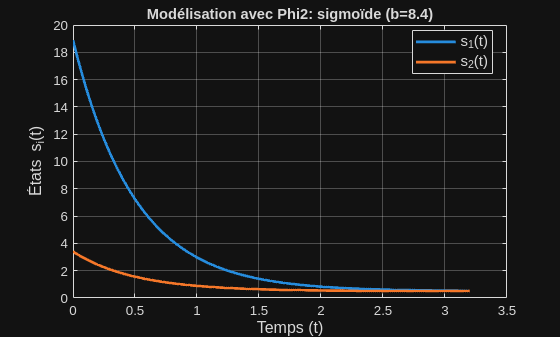

lambda_val =2;
s_01 =18.9;
s_02 =3.4;
B1 =1;
B2 =15.1;
w11 =5.7;
w12 =12.3;
w21 =5.5;
w22 =0;
b_param =8.4;
T = 3.2;
phi_choice = 2;
%% Tracé
tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param,T);

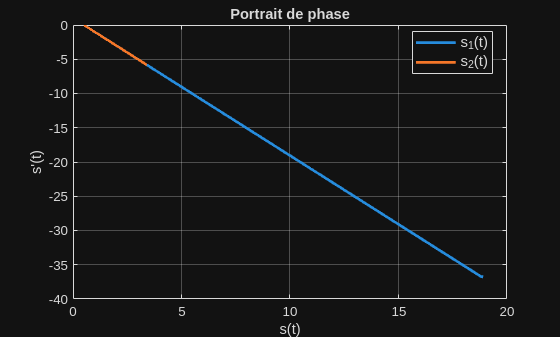

%% Tracé du portrait de phase
W = [w11, w12; w21, w22];
B = [B1; B2];
s0 = [s_01; s_02];
tspan = [0 T];
[t, s] = euler(W, B, s0, lambda_val, tspan, phi_choice, b_param);
n = 2;
N = length(s);
D=zeros(N,n);
for j=1:n;
    D(:,j) = gradient(s(:,j),t);
end
plot(s(:,1),D(:,1),'LineWidth', 2)
hold on;
plot(s(:,2),D(:,2),'LineWidth', 2)
xlabel("s(t)")
ylabel("s'(t)")
title("Portrait de phase")
grid on;
legend('s_1(t)', 's_2(t)', 'Location', 'best', 'FontSize', 11);
hold off;

#### Conclusion

Lambda permet d'ajuster la vitesse de convergence

Si l'on augmente beta, on augmente la raiedeur et donc la saturation sera plus rapide

####     II. Système à n neurones

#### Q2/ Exploration

%% Question 2 - Système à n neurones

clear all;
close all;
clc;

%% Définition du nombre de neurones
n = 5;

%% Fonctions

% Fonction d'activation selon phi_choice
function Phi = get_activation_function(phi_choice, beta)
    if phi_choice == 1
        % ReLU: max(0,x)
        Phi = @(x) max(0, x);
    else
        % Sigmoïde
        Phi = @(x) 1 ./ (1 + exp(-beta * x));
    end
end

% Méthode d'Euler
function [t, s] = euler2(W, B, s0, lambda, tspan, phi_choice, beta)
    n = length(s0);
    N = 1000;
    pas = (tspan(2) - tspan(1)) / N;

    Phi = get_activation_function(phi_choice, beta);
    
    f = @(t, s) -lambda * s + Phi(W * s + B); 
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, n);
    s(1, :) = s0';
    
    for i = 1:N
        f_i = f(t(i), s(i, :)'); 
        s(i+1, :) = s(i, :) + pas * f_i'; 
        t(i+1) = t(i) + pas;
    end
end

% Fonction de génération de matrice W
function W = generate_W_matrix(n, w_mode, w_diag, w_off, w_scale)
    switch w_mode
        case 1  % Uniforme
            W = w_off * ones(n, n);
            
        case 2  % Diagonale
            W = w_off * ones(n, n);
            W = W + (w_diag - w_off) * eye(n);
            
        case 3  % Aléatoire
            W = w_scale * (2 * rand(n, n) - 1);
            
        case 4  % Identité
            W = w_diag * eye(n);
            
        case 5  % Symétrique
            W_temp = w_scale * (2 * rand(n, n) - 1);
            W = (W_temp + W_temp') / 2;
            
        otherwise
            W = ones(n, n);
    end
end

% Fonction de génération de B
function B = generate_B(n, B_mode, B_off, B_scale)
    switch B_mode
        case 1  % Uniforme
            B = B_off * ones(1, n);

        case 2  % Aléatoire
            B = B_scale * (2 * rand(1, n) - 1);
            
        otherwise
            B = ones(1, n);
    end
end

% Fonction de génération de s0
function S = generate_s0(n, S_mode, S_off, S_scale)
    switch S_mode
        case 1  % Uniforme
            S = S_off * ones(1, n);

        case 2  % Aléatoire
            S = S_scale * (2 * rand(1, n) - 1);
            
        otherwise
            S = ones(1, n);
    end
end

% Fonction de tracé
function tracer_graph2(n, lambda, beta, phi_choice, s0_vec, B_vec, W_mat,T)
    tspan = [0 T];
    
    % Convertir les vecteurs
    s0 = s0_vec(:);
    B = B_vec(:);
    
    % Résolution
    [t, s] = euler2(W_mat, B, s0, lambda, tspan, phi_choice, beta);
    
    % Tracé
    plot(t, s, 'LineWidth', 2);
    xlabel('Temps (t)', 'FontSize', 12);
    ylabel('États s_i(t)', 'FontSize', 12);
    grid on;
    
    % Légende
    legend_labels = arrayfun(@(i) sprintf('s_%d(t)', i), 1:n, 'UniformOutput', false);
    legend(legend_labels, 'Location', 'best', 'FontSize', 10);
    
    % Titre
    if phi_choice == 1
        func_name = 'ReLU: max(0,x)';
    else
        func_name = sprintf('Sigmoïde (β=%.1f)', beta);
    end
    title(sprintf('Système à %d neurones - %s - λ=%.2f', n, func_name, lambda), 'FontSize', 11);
end

%% Initialisation des paramètres par défaut
% Ces valeurs sont utilisées au premier lancement

% Paramètres de l'équation
lambda = 2;
beta = 1;
phi_choice = 1;  % 1 = ReLU, 2 = Sigmoïde

% Conditions initiales et externes (uniformes)
s0_uniform = 1;
B_uniform = 1;

% Paramètres de génération de la matrice W
w_mode = 2;      % 1=Uniforme, 2=Diagonale, 3=Aléatoire, 4=Identité, 5=Symétrique
w_diag = 2;
w_off = 0.5;
w_scale = 1;

% Paramètres de génération de B
B_mode = 2;      % 1=Uniforme, 2=Aléatoire
B_off = 0.5;
B_scale = 100;

% Paramètres de génération de s0
S_mode = 2;      % 1=Uniforme, 2=Aléatoire
S_off = 0.5;
S_scale = 100;

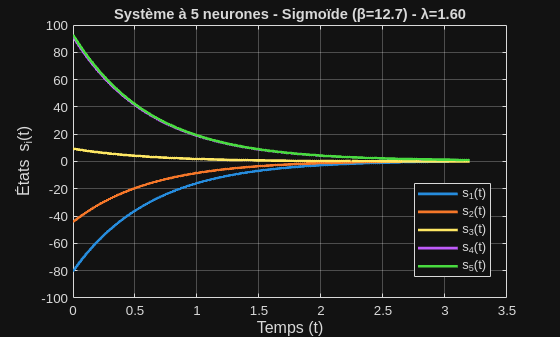

lambda =1.6;
beta =12.7;
w_mode = 4;
w_off =9.6;
B_mode = 2;
B_off =4.1;
S_mode = 2;
S_off =16.4;
phi_choice = 2;
T = 3.2;

% Génération de la matrice W selon le mode choisi
W_mat = generate_W_matrix(n, w_mode, w_diag, w_off, w_scale);

% Génération de B selon le mode choisi
B_vec = generate_B(n, B_mode, B_off, B_scale);

% Génération de S selon le mode choisi
s0_vec = generate_s0(n, S_mode, S_off, S_scale);

% Tracé
tracer_graph2(n, lambda, beta, phi_choice, s0_vec, B_vec, W_mat,T);

disp(B_vec)

   62.9447   81.1584  -74.6026   82.6752   26.4718



disp(W_mat)

     2     0     0     0     0
     0     2     0     0     0
     0     0     2     0     0
     0     0     0     2     0
     0     0     0     0     2



#### Q3/ Système à n neurones - On veut trouver numériquement W ∗ qui minimise H(W ) sur Mn (R)

- Calcul des dérivées partielles

n = 10;     % Nombre de si
T = 5;      % [0, T] est l'intervalle sur lequel y est défini ici 
tspan = [0, T];

phit = @(x) 1 ./ (1 + exp(-x));
dphi = @(x) exp(-x) ./ (1 + exp(-x) ).^2;

B = ones(n,1) + (1:n)'/(n-1);
W0 = zeros(n, n);

% On a supposé lambda = 1
R = 9 - 80/n - abs((1:n)' - n/2)/n;
A = -2*eye(n) + diag(ones(n-1, 1), 1) + diag(ones(n-1, 1), -1);

xi = @(s) (A * s) + (R - 0.5*sum(s)) .* s;


%% Réolution de y

% y est la solution de l'EDO y' = xi(y). On l'estime avec la méthode
% d'Euler explicite

h_euler = 0.01;   % pas
Npas = T/h_euler;     % nombre de pas 


y = zeros(n, Npas + 1); % 1 ligne par composantes, 1 colonne par instant t = j*h
y(:,1) = 0.25 * (ones(n,1) - 0.5 * (1:n)'/ (n-1));     % initialisation de y


for j=1:Npas        % méthode d'euler 
   y(:,j+1) = y(:,j) + h_euler * xi(y(:,j));
end


%% Estimation des dérivées de H par rapport à wij (pour faire après la descente de gradient)

function [I] = dH(W,y,B,dphi,phit)
    % Cette fonction renvoie le gradient de H 
    n = 10;

    R = 9 - 80/n - abs((1:n)' - n/2)/n;
    A = -2*eye(n) + diag(ones(n-1, 1), 1) + diag(ones(n-1, 1), -1);
    
    % Calcul de xi de y préalable : 
    xiy_matrice = A * y + ((R - (1/2)*sum(y, 1)) .* y);
    
    T = 5;
    h_integrale = 0.01;    % pas
    N = T/h_integrale;
    
    % Ce que l'on intègre pour calculer le gradient 
    
    E = -y + phit(W * y + B) - xiy_matrice;
    I = 2 * (E .* dphi(-W * y + B)) * y' * h_integrale;
    

end

% res11 = dH(1,1,W0,y,B,dphi,phit,xi)
% 
% res12 = dH(1,1,Wstar,y,B,dphi,phit,xi)
% 
% res13 = dH(4,5,Wstar,y,B,dphi,phit,xi)



%% Descente de gradient à pas fixe (Q3)

Niter = 1000000;
pas = 1;     % Pas pour la descente de gradient 
U = W0;         % matrice carrée sur laquelle on va itérer 

for k = 1:Niter             % Descente de gradient 
    grad = dH(U,y,B,dphi,phit);
    
    U = U - pas * grad;

end

Wstar = U;

%% Valeur de H(Wstar)

function [I] = H(W,y,B,phit,xi)
    % La fonction H
    
    T = 5;
    h = 0.01;    % pas
    N = T/h;
    
    integrande = @(t) norm(phit(W * y(:,t) + B) - y(:,t) - xi(y(:,t))) ^ 2;
    
    I = 0;
    for k=1:N
       I = I + h.*integrande(k); % k correspond au rang de l'instant d'évaluation, qui vaut k*h
    end

end

HdeWstar = H(Wstar, y, B, phit, xi)

HdeWstar = 0.0022



%% Vérification de résolution en calculant la solution associée à Wstar s :  


% Résolution de s avec Wstar : 
function [t, s] = euler3(W, B, s0, lambda, tspan, Phi, T)
    n = length(s0);
    N = T / 0.01;
    pas = (tspan(2) - tspan(1)) / N;
    
    f = @(t, s) -lambda * s + Phi(W * s + B); 
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, n);
    s(1, :) = s0';
    
    for i = 1:N
        f_i = f(t(i), s(i, :)'); 
        s(i+1, :) = s(i, :) + pas * f_i'; 
        t(i+1) = t(i) + pas;
    end
    s = s';
end


[t, s] = euler3(Wstar, B, y(:, 1), 1, tspan, phit, T);


function [I] = norme(y, s, T)
    % La norme de y-s

    h = 0.01;    % pas
    N = T/h;
    
    integrande = @(t) sum((y(:, t) - s(:, t)).^2);
    
    I = 0;
    for k=1:N   % Méthode du gradient
       I = I + h.*integrande(k); % k correspond au rang de l'instant d'évaluation, qui vaut k*h
    end

    I = sqrt(I);

end

difference_y_s = norme(y, s, T)

difference_y_s = 0.0174

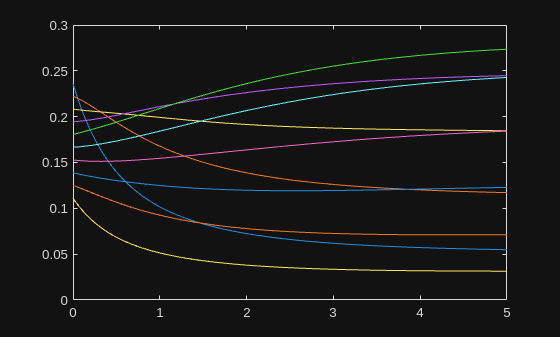



%% tracés 

% tracé de y 
figure;
tk = linspace(0, T, length(y(1, :)));
if(1)
   for k = 1:length(y(:,1))
       plot(tk, y(k,:));
       ylim([0 0.3]);
       hold on
   end
   hold off
end

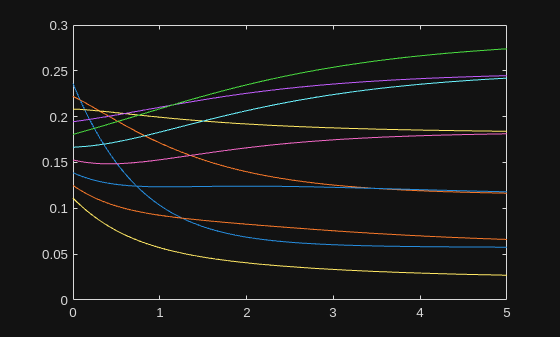


% tracé de s 
figure;
tk2 = linspace(0, T, length(s(1, :)));
if(1)
   for k = 1:length(s(:,1))
       plot(tk2, s(k,:));
       ylim([0 0.3]);
       hold on
   end
   hold off
end

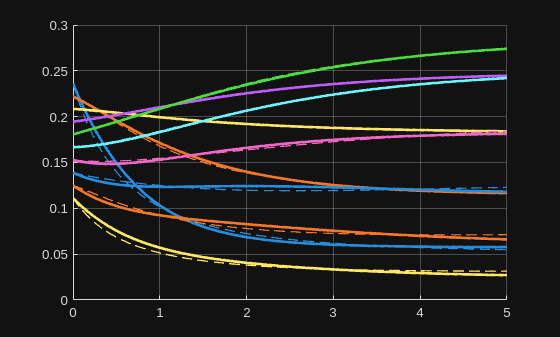



% Tracé superposé
colors = lines(size(s,1));

figure;
hold on;
for k = 1:length(s(:,1))

   plot(tk2, s(k,:), "LineStyle", "-", 'Color', colors(k,:), 'LineWidth', 2);
   plot(tk, y(k,:), "LineStyle", "--", 'Color', colors(k,:), 'LineWidth', 1);

end
ylim([0 0.3]);
grid on;
hold off

####     III. Prise en compte des incertitudes

#### Q4/ Propagation des incertitudes

- Hypothèse: les données initiales du système sont distribuées selon des lois normales indépendantes

function[p,R0]=M(N,sigma,seuil,T)
    tspan = [0 T]; 
    s0_01=0;
    s0_02=0;
    s0_ref = [s0_01; s0_02];
    W = [1, 1; 1, 1];
    B = [1; 1];
    lambda_val = 2;
    phi_choice = 2; % 1 pour Phi1, 2 pour Phi2
    b_param = 1;
    somme=0;
    R0=zeros(N,1); %Vecteur qui garde en mémoire la norme entre la solution de réference et la solution perturbée
    [t_0, s_ref] = euler(W, B, s0_ref, lambda_val, tspan, phi_choice, b_param);
    for i=1:N
        % Géneration des conditions initales perturbées
        s_01=normrnd(s0_01,sigma);
        s_02=normrnd(s0_02,sigma);
        s0_perturbe=[s_01;s_02];
        % Calcul de la solutions pertubées
        [t_1, s_perturbe] = euler(W, B, s0_perturbe, lambda_val, tspan, phi_choice, b_param);
        % Calcul de la norme de la différence
        diff=s_perturbe-s_ref;
        L_norm=sqrt(trapz(t_1,sum(diff.^2,2)));
        R0(i)=L_norm;
        if L_norm>seuil 
            somme=somme+1;
        end
    end
    p=somme/N; 
end
N=1000; % Nombre d'itérations de la méthode de Monte Carlo
[p,R0]=M(N,1,1,50);
p

p = 0.1420

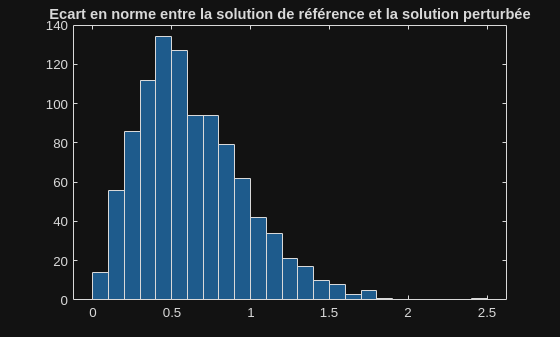

histogram(R0)
title('Ecart en norme entre la solution de référence et la solution perturbée');

        2. Incertitude sur le calcul

Avec la méthode de Monte Carlo on approche donc une probabilité par la réalisation d’une variable aléatoire. Il n’est donc pas possible de caractériser avec certitude l’erreur d’approximation que l’on commet. L'on calcul donc un intervalle de confiance :

% Intervalle de confiance à 90%
N = 1000;
a=0.1;
p_inf = p - norminv(1-a/2)*sqrt(p*(1-p)/N)

p_inf = 0.1238

p_sup = p + norminv(1-a/2)*sqrt(p*(1-p)/N)

p_sup = 0.1602

       3. Variabilité sur les données d'entrée

On teste différente valeurs possible pour la variance de la loi normale (c'est ce qui contrôle la variabilité des données) jusqu'à obtenir une variance de la loi normale tel que la probabilité que la norme ne d´epasse δ soit inférieur à 0.1.

seuil=1;
N=100;
sigma=linspace(5,0,50);
i=1;
while M(N,sigma(i),seuil,5) >0.1
    i=i+1;
end
sigma(i)

ans = 0.9184

#### **Q5/ **

%code